Cd0=0.017

Cd0 = 0.0170

AR=3

AR = 3

e=1.78*(1-0.045*AR^0.68)-0.64

e = 0.9709

k=1/(pi*AR*e) 

k = 0.1093

Cl0=0

Cl0 = 0

Cl_alpha=0.1017

Cl_alpha = 0.1017

Cl_dele=0.0056

Cl_dele = 0.0056

Cm0=0.053822

Cm0 = 0.0538

Cm_alpha=-0.0109

Cm_alpha = -0.0109

Cm_dele=0.0082

Cm_dele = 0.0082


w_s=1200

w_s = 1200

s=2.4

s = 2.4000

ceiling=11000

ceiling = 11000

sigma=(1-6.873*10^(-6)*ceiling)^4.26

sigma = 0.7154

dele=-15:1:15

dele =    -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15


dele=dele*pi/180

dele =    -0.2618   -0.2443   -0.2269   -0.2094   -0.1920   -0.1745   -0.1571   -0.1396   -0.1222   -0.1047   -0.0873   -0.0698   -0.0524   -0.0349   -0.0175         0    0.0175    0.0349    0.0524    0.0698    0.0873    0.1047    0.1222    0.1396    0.1571    0.1745    0.1920    0.2094    0.2269    0.2443    0.2618


alpha_trim=-(Cm0+Cm_dele*dele)/Cm_alpha

alpha_trim =     4.7408    4.7540    4.7671    4.7802    4.7934    4.8065    4.8196    4.8328    4.8459    4.8590    4.8721    4.8853    4.8984    4.9115    4.9247    4.9378    4.9509    4.9641    4.9772    4.9903    5.0034    5.0166    5.0297    5.0428    5.0560    5.0691    5.0822    5.0954    5.1085    5.1216    5.1347


CL_trim=Cl0+Cl_alpha*alpha_trim+Cl_dele*dele

CL_trim =     0.4807    0.4821    0.4835    0.4850    0.4864    0.4878    0.4893    0.4907    0.4921    0.4936    0.4950    0.4964    0.4979    0.4993    0.5007    0.5022    0.5036    0.5050    0.5065    0.5079    0.5093    0.5108    0.5122    0.5136    0.5151    0.5165    0.5179    0.5194    0.5208    0.5222    0.5237


Cd_trim=Cd0+k*CL_trim.^2

Cd_trim =     0.0422    0.0424    0.0426    0.0427    0.0429    0.0430    0.0432    0.0433    0.0435    0.0436    0.0438    0.0439    0.0441    0.0442    0.0444    0.0446    0.0447    0.0449    0.0450    0.0452    0.0454    0.0455    0.0457    0.0458    0.0460    0.0462    0.0463    0.0465    0.0466    0.0468    0.0470


V_trim=sqrt(2*w_s./(row*sigma.*CL_trim))

V_trim =    75.4800   75.3677   75.2559   75.1447   75.0339   74.9236   74.8138   74.7045   74.5956   74.4873   74.3794   74.2719   74.1650   74.0585   73.9524   73.8468   73.7417   73.6370   73.5327   73.4289   73.3255   73.2226   73.1201   73.0180   72.9164   72.8152   72.7144   72.6140   72.5140   72.4144   72.3153


Tr_trim=(0.5*row*sigma*s*V_trim.^2).*(Cd0+k*CL_trim.^2)

Tr_trim =   253.1388  253.2871  253.4371  253.5890  253.7425  253.8979  254.0550  254.2138  254.3743  254.5364  254.7003  254.8658  255.0330  255.2017  255.3721  255.5441  255.7177  255.8929  256.0696  256.2479  256.4277  256.6090  256.7919  256.9762  257.1620  257.3493  257.5381  257.7283  257.9199  258.1130  258.3074


Pr_trim=Tr_trim.*V_trim

Pr_trim = 	1.0e+04 *

    1.9107    1.9090    1.9073    1.9056    1.9039    1.9023    1.9007    1.8991    1.8975    1.8960    1.8944    1.8929    1.8915    1.8900    1.8885    1.8871    1.8857    1.8843    1.8829    1.8816    1.8803    1.8790    1.8777    1.8764    1.8751    1.8739    1.8727    1.8715    1.8703    1.8691    1.8680


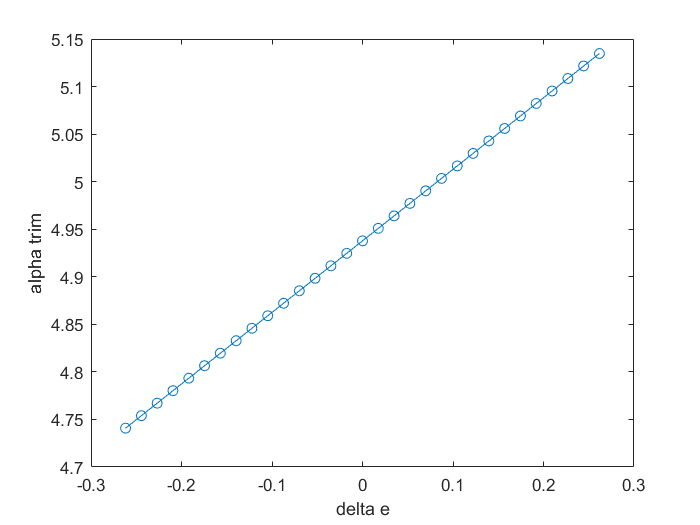

plot(dele,alpha_trim,"Marker","o")
xlabel("delta e")
ylabel("alpha trim")

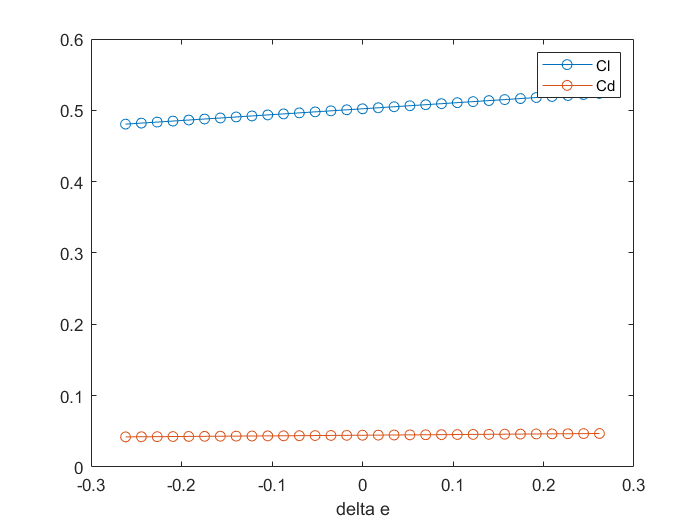

plot(dele,CL_trim,"Marker","o")
hold on
plot(dele,Cd_trim,"Marker","o")
hold off
xlabel("delta e")
legend("Cl","Cd")

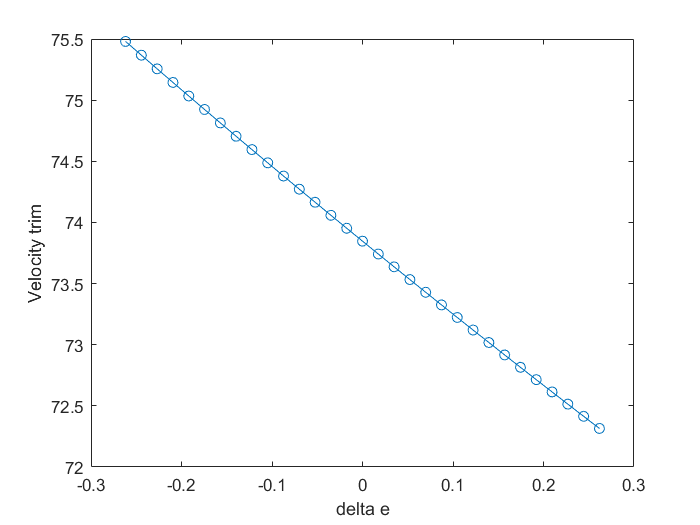

plot(dele,V_trim,"Marker","o")
xlabel("delta e")
ylabel("Velocity trim")

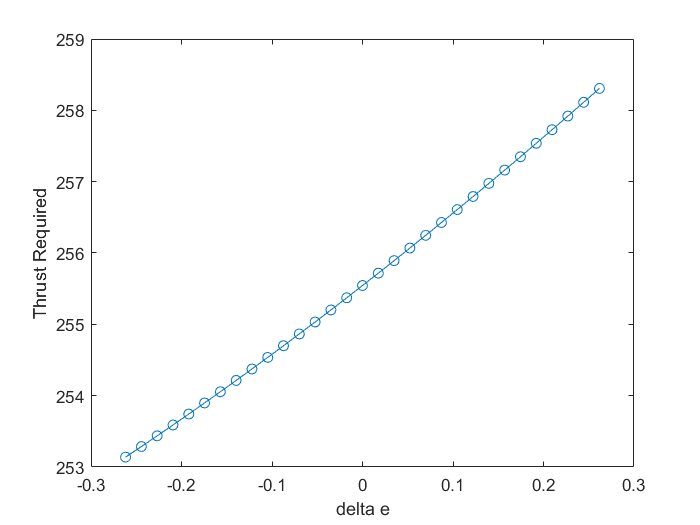

plot(dele,Tr_trim,"Marker","o")
xlabel("delta e")
ylabel("Thrust Required")

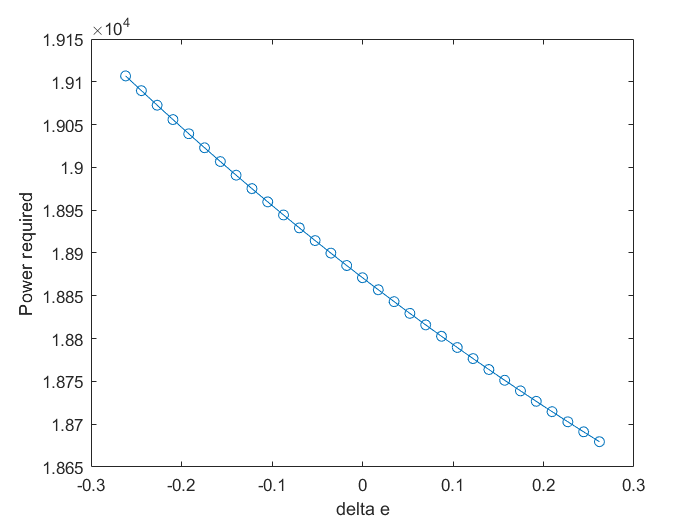

plot(dele,Pr_trim,"Marker","o")
xlabel("delta e")
ylabel("Power required")